# Návrh regulátoru metodou Ziegler-Nicholse

## Vymazání proměnných z workspace, získání parametrů soustavy pro model

clc;
close all;
clearvars;
ID  = 256421;
[A, D, g, rho, J, B, ke, R, L, C, Fs, Fv] = gen_sys2025(ID);


Fs =
 
            5.7621e+11
  ------------------------------
  (s+694.2)^2 (s+19.1) (s+3.732)
 
Continuous-time zero/pole/gain model.
Model Properties

Fv =
 
  -1551.4 (s+1190) (s+220.4) (s+0.7153)
  -------------------------------------
     (s+694.2)^2 (s+19.1) (s+3.732)
 
Continuous-time zero/pole/gain model.


## Stanovení kritických parametrů (důkaz správnosti výpočtu na papír)

[Kkrit,~,wkrit,~] = margin(Fs)

Kkrit = 0.0068

wkrit = 88.6881

# Návrh PI regulátoru

## Dopočítání Kp, Tkrit a Ti

Tkrit = 2*pi/wkrit;
Kp = 0.4*Kkrit;
Ti = 0.85*Tkrit; 

## Inicializace řídicího signálu, inicializace poruchy

t = 0:1e-4:4;
ug_data = 5*ones(size(t));
ug = timeseries(ug_data, t);
iz_data = 0.02* (t > 0.5);
iz = timeseries(iz_data, t);
out_pi = sim("ZNmodPI.slx");

## Vykreslení naměřených charakteristik

figure;
title(tiledlayout(3,2,"TileSpacing","loose"), "Charakteristiky řízení hydrogenerátoru pomocí PI regulátoru navrženého metodou ZN");

- Objemový průtok (akční zásah)

nexttile;
plot(out_pi.Qin.Time, out_pi.Qin.Data);
grid on;
title('Q_{in} (t)');
xlabel('t [s]');
ylabel('Q_{in} [m^3\cdot s^{-1}]');

- Výška hladiny

nexttile;
plot(out_pi.h.Time, out_pi.h.Data);
grid on;
title('h(t)');
xlabel('t [s]');
ylabel('h [m]');

- Regulační odchylka

nexttile;
plot(out_pi.e.Time, out_pi.e.Data);
grid on;
title('e(t)');
xlabel('t [s]');
ylabel('e [V]');

- Proud tekoucí kotvou DC generátoru

nexttile;
plot(out_pi.i.Time, out_pi.i.Data);
grid on;
title('i(t)');
xlabel('t [s]');
ylabel('i [mA]');

- Napětí na výstupu hydrogenerátoru

nexttile;
plot(out_pi.ug.Time, out_pi.ug.Data);
grid on;
title('U_g(t)');
xlabel('t [s]');
ylabel('u_g [V]');

- Úhlová rychlost DC generátoru

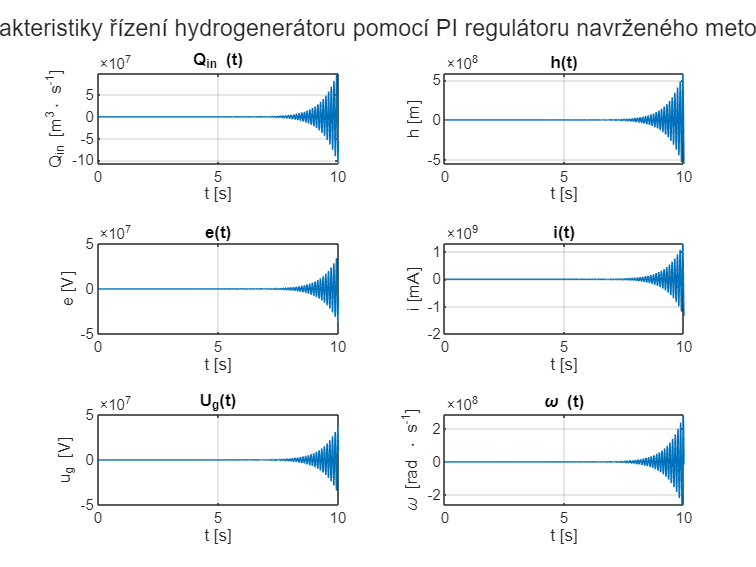

nexttile;
plot(out_pi.w.Time, out_pi.w.Data);
grid on;
title('\omega (t)');
xlabel('t [s]');
ylabel('\omega [rad \cdot s^{-1}]');

### Export naměřených charakteristik do nového .pdf souboru

if isfile("ZNPI.pdf")
    delete("ZNPI.pdf");
end
exportgraphics(gcf, 'ZNPI.pdf', 'ContentType', 'vector');

# Návrh PID regulátoru

- Vypočtení hodnot Kp, Ti, Td

Ti = 0.5*Tkrit;
Kp = 0.6*Kkrit;
Td = 0.125*Tkrit;

- Nastavení parametrů pro grafický výstup

t = 0:1e-4:0.9;
ug_data = 5*ones(size(t));
ug = timeseries(ug_data, t);
iz_data = 0.02* (t > 0.5);
iz = timeseries(iz_data, t);

## PID regulátor s realizační konstantou N = 10

N = 10;
out_pid = sim("ZNmodPID.slx");
figure;
title(tiledlayout(3,2,"TileSpacing","loose"), 'Charakteristiky řízení hydrogenerátoru reálným PID regulátorem navrženým metodou Ziegler-Nichols (N = 10)');
nexttile;

- Vstupní objemový průtok

p = plot(out_pid.Qin.Time, out_pid.Qin.Data);
grid on;
title('Q_{in} (t)');
xticks([0,0.2,0.4,0.6,0.8]);
yticks([-50, 0, 50, 100, 200]);
Q_ss = 0.228;
yline(Q_ss,'--k',sprintf('Q_{in} = %.f ml/s',Q_ss*1000),'LineWidth',1.3);
xlim([0 0.9]);
xregion(0.4,0.47,'FaceColor', "r");
xlabel('t [s]');
ylabel('Q_{in} [dm^3\cdot s^{-1}]');
nexttile;

- Výška hladiny [m]

plot(out_pid.h.Time, out_pid.h.Data);
grid on;
title('h(t)');
xlabel('t [s]');
ylabel('h [cm]');
h1 = 29.58;
h2 = 33.98;
yline(h1,'--k','LineWidth',0.7);
yline(h2,'--r',sprintf('h_2 =%.f cm (\\Delta h = %.f cm)', h2, h2 - h1),'LineWidth',0.7);
xlim([0 0.9]);
xregion(0.4,0.9,'FaceColor', "y");
nexttile;

- Regulační odchylka [V]

plot(out_pid.e.Time, out_pid.e.Data);
grid on;
title('e(t)');
xlabel('t [s]');
ylabel('e [V]');
xregion(0.4,0.47,'FaceColor', "r");

xlim([0 0.9]);
nexttile;

- Výstupní proud z hydrogenerátoru

plot(out_pid.i.Time, out_pid.i.Data);
grid on;
title('i(t)');
xlabel('t [s]');
ylabel('i [mA]');
xlim([0 0.9]);
xregion(0.4,0.9,'FaceColor', "y");
i1 = 0;
i2 = 20;
yline(i1,'--k','LineWidth',0.7);
yline(i2,'--r',sprintf('\\Delta i = i_z = %.f mA', i2 - i1),'LineWidth',0.7);
nexttile;

- Průběh napětí [V]

plot(out_pid.ug.Time, out_pid.ug.Data);
grid on;
title('U_g(t)');
xlabel('t [s]');
ylabel('u_g [V]');
xregion(0.4,0.47,'FaceColor', "r");
xlim([0 0.9]);
nexttile;

- Průběh úhlové rychlosti

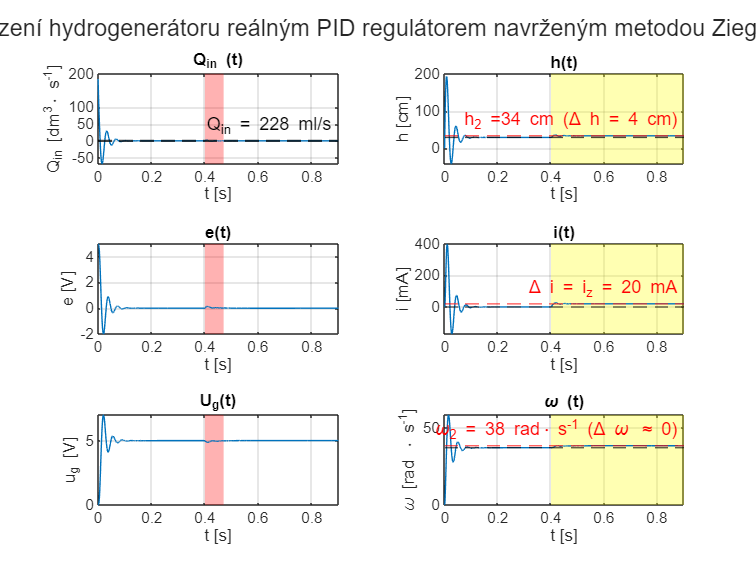

plot(out_pid.w.Time, out_pid.w.Data);
grid on;
w1 = 37.03;
w2 = 38.31;
title('\omega (t)');
yline(w1,'--k','LineWidth',0.7);
yline(w2,'--r',sprintf('\\omega_2 = %.f rad\\cdot s^{-1} (\\Delta \\omega \\approx 0)', w2),'LineWidth',0.7);
xlabel('t [s]');
xlim([0 0.9]);
xregion(0.4,0.9,'FaceColor', "y");
ylabel('\omega [rad \cdot s^{-1}]');

### Export naměřených charakteristik do nového .pdf souboru

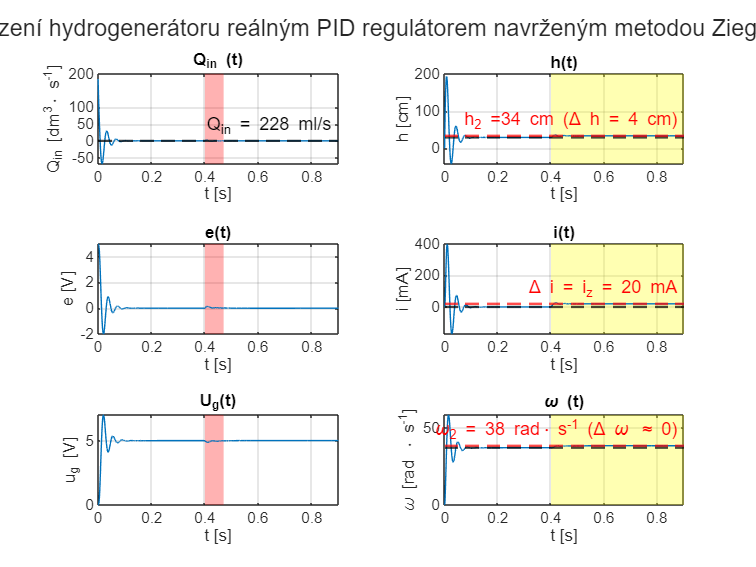

if isfile("ZNPID10.pdf")
    delete("ZNPID10.pdf");
end

exportgraphics(gcf, 'ZNPID10.pdf', 'ContentType', 'vector');

## PID regulátor s realizační konstantou N = 100

N = 100;
out_pid = sim("ZNmodPID.slx");
title(tiledlayout(3,2,"TileSpacing","loose"), 'Charakteristiky řízení hydrogenerátoru reálným PID regulátorem navrženým metodou Ziegler-Nichols (N = 100)');
nexttile;

- Vstupní objemový průtok

p = plot(out_pid.Qin.Time, out_pid.Qin.Data);
grid on;
title('Q_{in} (t)');
xticks([0.3,0.4,0.6,0.8]);
yticks([1000, 2000]);
Q_ss = 0.228;
yline(Q_ss,'--k',sprintf('Q_{in} = %.f ml/s',Q_ss*1000),'LineWidth',1.3);
xlim([0 0.9]);
xregion(0.4,0.47,'FaceColor', "r");
xlabel('t [s]');
ylabel('Q_{in} [dm^3\cdot s^{-1}]');
nexttile;

- Výška hladiny [m]

plot(out_pid.h.Time, out_pid.h.Data);
grid on;
title('h(t)');
xlabel('t [s]');
ylabel('h [cm]');
h1 = 29.58;
h2 = 33.98;
yline(h1,'--k','LineWidth',0.7);
yline(h2,'--r',sprintf('h_2 =%.f cm (\\Delta h = %.f cm)', h2, h2 - h1),'LineWidth',0.7);
xlim([0 0.9]);
xregion(0.4,0.9,'FaceColor', "y");
nexttile;

- Regulační odchylka [V]

plot(out_pid.e.Time, out_pid.e.Data);
grid on;
title('e(t)');
xlabel('t [s]');
ylabel('e [V]');
xregion(0.4,0.47,'FaceColor', "r");

xlim([0 0.9]);
nexttile;

- Výstupní proud z hydrogenerátoru

plot(out_pid.i.Time, out_pid.i.Data);
grid on;
title('i(t)');
xlabel('t [s]');
ylabel('i [mA]');
xlim([0 0.9]);
xregion(0.4,0.9,'FaceColor', "y");
i1 = 0;
i2 = 20;
yline(i1,'--k','LineWidth',0.7);
yline(i2,'--r',sprintf('\\Delta i = i_z = %.f mA', i2 - i1),'LineWidth',0.7);
nexttile;

- Průběh napětí [V]

plot(out_pid.ug.Time, out_pid.ug.Data);
grid on;
title('U_g(t)');
xlabel('t [s]');
ylabel('u_g [V]');
xregion(0.4,0.47,'FaceColor', "r");
xlim([0 0.9]);
nexttile;

- Průběh úhlové rychlosti

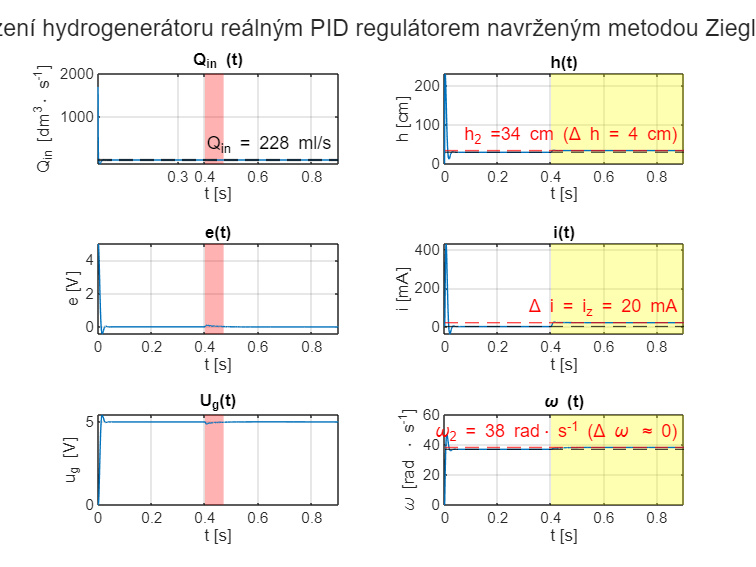

plot(out_pid.w.Time, out_pid.w.Data);
grid on;
w1 = 37.03;
w2 = 38.31;
title('\omega (t)');
yline(w1,'--k','LineWidth',0.7);
yline(w2,'--r',sprintf('\\omega_2 = %.f rad\\cdot s^{-1} (\\Delta \\omega \\approx 0)', w2),'LineWidth',0.7);
xlabel('t [s]');
xlim([0 0.9]);
ylim([0 60]);
yticks([0, 20, 40, 60]);
xregion(0.4,0.9,'FaceColor', "y");
ylabel('\omega [rad \cdot s^{-1}]');

### Export naměřených charakteristik do nového .pdf souboru

if isfile("ZNPID100.pdf")
    delete("ZNPID100.pdf");
end
exportgraphics(gcf, 'ZNPID100.pdf', 'ContentType', 'vector');